# Simple processing with the approximate Pake transformation (APT)

#### Author: Luis Fabregas

This tutorial focuses on how to use the old approximate Pake transformation (APT) technique, which was commonly found in the old DeerAnalysis. Although fast, its results can be very rough approximations of the underlying truth and hence its use its not recomended for a final analysis of experimental data.

## Simulating a dipolar signal

Let's start by simulating a very simple dipolar evolution function (i.e. no background and 100% modulation depth), whose parameters we know. 

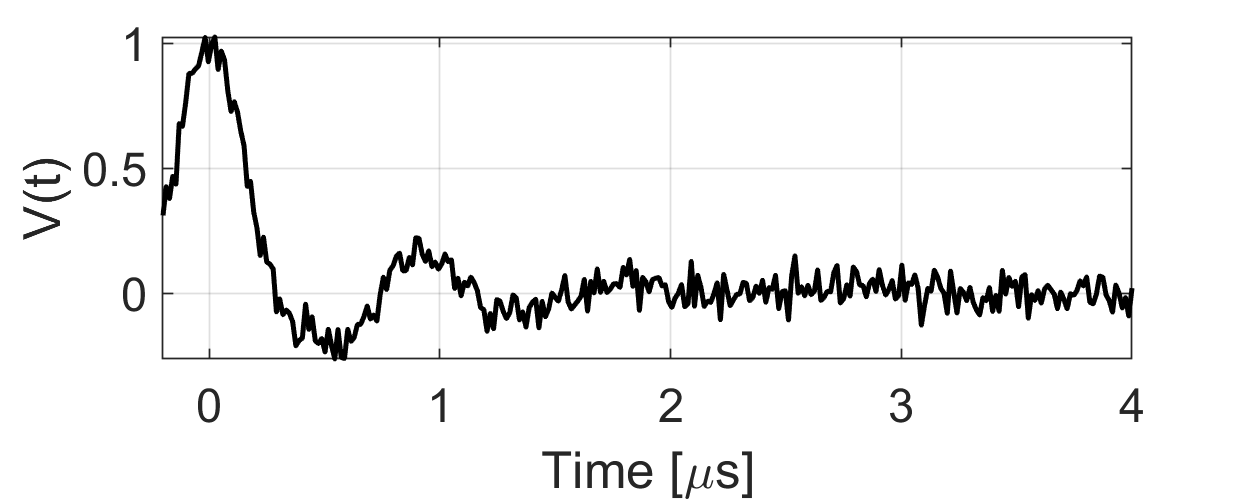

t = linspace(-0.2,4,300);
r = linspace(2,5,250);

%Generate the distance distribution
P = rd_onegaussian(r,[3.5 0.3]);
%Generate the signal
D = dipolarsignal(t,r,P,'noiselevel',0.05);

%Plot
figure('position',[0 0 500 200])
plot(t,D,'k','Linewidth',1.5)
set(gca,'fontsize',14)
axis tight, grid on
xlabel('Time [\mus]'),ylabel('V(t)')

## Generating the APT kernel

The APT relies on an integral transformation from time-domain to frequency-domain with a posterior mapping to distance-domain. This means that the kernel describing this trasnformation cannot be constructed via the `dipolarkernel` function. For this the `aptkernel` function must be used.

%Generate the APT kernel
Kapt = aptkernel(t);

## Simple APT

With the APT kernel in hand we can proceed to run the APT and obtain the approximation of the underlying distance distribution.

%Compute the APT
[Papt,rapt] = apt(D,Kapt);

Since in this tutorial we know the ground truth we can compare the results

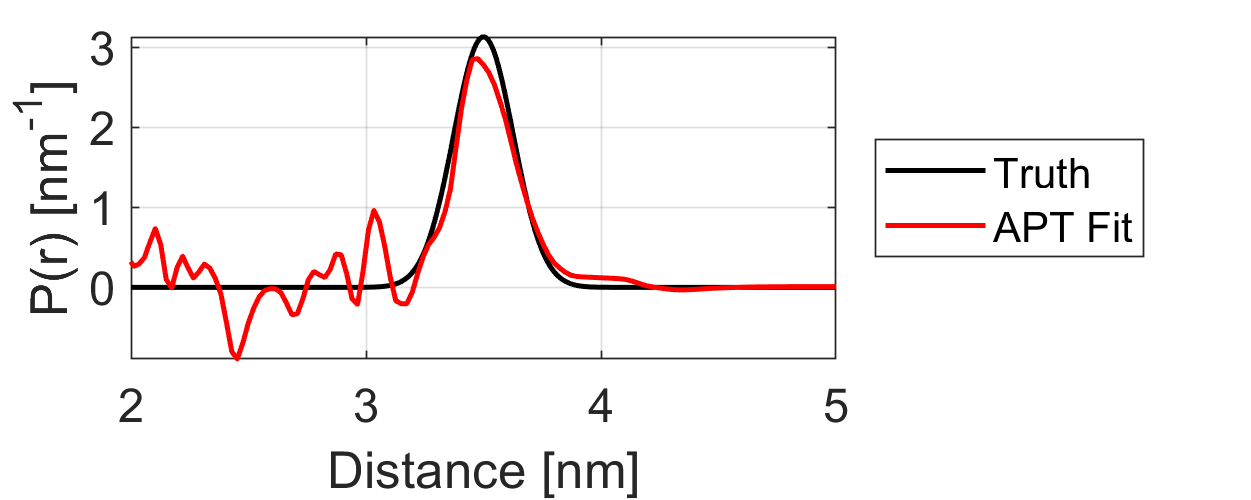

%Plot results
figure('position',[0 0 500 200])
plot(r,P,'k',rapt,Papt,'r','Linewidth',1.5)
axis tight, grid on, legend('Truth','APT Fit','Location','eastoutside')
set(gca,'fontsize',14,'xlim',[2 5])
xlabel('Distance [nm]'),ylabel('P(r) [nm^{-1}]')

## Playing with the DDS parameter

While the APT is fully described and defined by the APT-kernel, we can control the shape of the distance distribution to some degree by means of the so-called distance-domain smoothing (DDS) parameter. In this section we will experiment with the influence the DDS-values have on the APT results. By default, if not specified the `apt` function uses a DDS of 0.05, so let's see what larger values lead to. We can see that increasing the DDS parameter helps supressing the oscillations at shorter distances at the cost of a considerable broadening of the distribution.

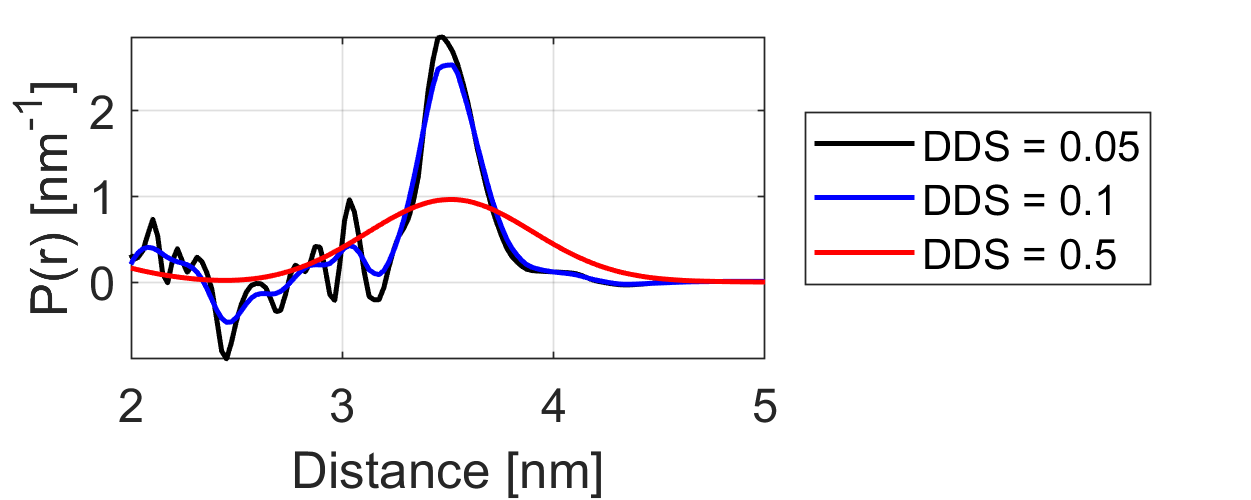

%Compute the APT
Papt1 = apt(D,Kapt,0.005);
Papt2 = apt(D,Kapt,0.1);
Papt3 = apt(D,Kapt,0.5);

%Plot results
figure('position',[0 0 500 200])
plot(rapt,Papt,'k',rapt,Papt2,'b',rapt,Papt3,'r','Linewidth',1.5)
axis tight, grid on, legend('DDS = 0.05','DDS = 0.1','DDS = 0.5','Location','eastoutside')
set(gca,'fontsize',14,'xlim',[2 5])
xlabel('Distance [nm]'),ylabel('P(r) [nm^{-1}]')